# Demo 10

% demo to get easy data from a VLP simulation using a sensor with
% photodiodes and light emitters

% n_Emitters -> number of light emitters
% x_Emitters -> number of light emitters per X
% y_Emitters -> number of light emitters per Y

## Prepare the Workspace

clear all;
close all;

% add the path to the projective geometry function
addpath('../projgeom/')


## Set the light emitters variables

n_Emitters = 16;        % Number of emitters
Pb = 0.5;               % Transmitted power
Ps = 0.0025;            %
m = 4;                  % Lambertian mode number

x_Emitters = 4;
y_Emitters = 4;


## Create and plot the light emitters

Emitters = newEmitters(n_Emitters, Pb, Ps, m);

%Considering a room with
Em_Base_HTM = Trans3(1.5,1.5,2)*RotX3(pi);      % 3m x 3m x 2m (WxLxH)

Emitters_per_row = 3 / x_Emitters

Emitters_per_row = 0.7500

Emitters_per_columns = 3 / y_Emitters

Emitters_per_columns = 0.7500

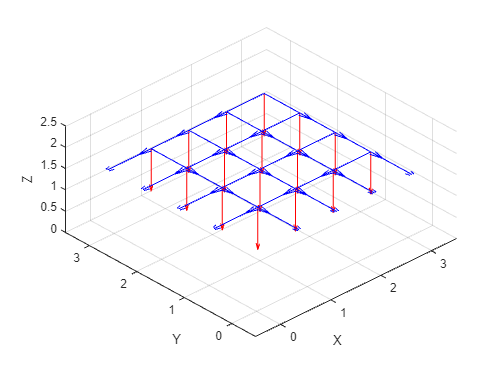


row_light = 1;
column_light = 1;

for i = 1:n_Emitters
    Emitters(i).HTM = Em_Base_HTM * Trans3(-1.5 - (Emitters_per_row / 2) + (Emitters_per_row * row_light) ,1.5 + (Emitters_per_columns/2) - Emitters_per_columns * column_light,0) * RotZ3(pi/2);
    row_light = row_light + 1;
    if row_light > x_Emitters
        row_light = 1;
        column_light = column_light + 1;
    end
end

figure()
PlotHTMArray(Emitters);
axis([-0.5 3.5 -0.5 3.5 0 2.5]);
view(3);
ylabel('Y')
xlabel('X')
zlabel('Z')
grid on
view([-43.35 53.33]);

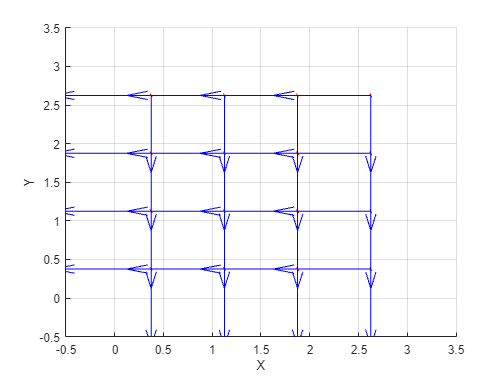


figure()
PlotHTMArray(Emitters);
axis([-0.5 3.5 -0.5 3.5 0 2.5]);
view(3);
ylabel('Y')
xlabel('X')
grid on
view([0 90.00])

## Set the receivers variables

Np = 3;                     % Number of parallels in the sensor
Nm = 4;                     % Number of meridians in the sensor
n_Receivers = Np*Nm;        % Number of receivers
Ar = 1e-6;                  % Active receiving area
Ts = 1;                     % Optical filter gain
n = 1;                      % Receiver's internal refractive index
Psi = pi/4;                 % Hemi-Fov
R = 1;                      % Receiver's responsivity


## Create and plot the receiver

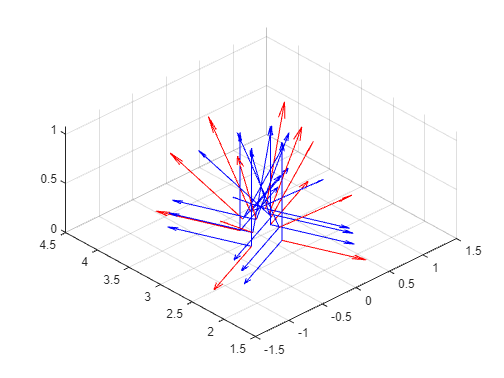

% Create the receiver structure:
Receivers = newReceivers(n_Receivers,Ar, Ts, n, Psi, R);
% Receivers are organized in Parallel and Meridians arragement of photo
% detectors, with Nm Meridians and 3 Parallels, in a sphere with
% radius=0.25
PDSensor = vlpCreateSensorParMer(Receivers, Np, Nm, 0.25,pi/8);

% The sensor is initially placed at point (X,Y) = (1.5,1.5,0)
PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

figure(40)
PlotHTMArray(PDSensor);
view(3);
grid on;
view([-43.35 53.33]);




% for i=1:8
%     % Calculate the position of the point on the circle
% %     x = r * cos(pi/4)
% %     y = r * sin(pi/4)
%     PDSensor = vlpMoveSensor(PDSensor, Trans3(-1.5,-1.5,0));
%     PDSensor = vlpMoveSensor(PDSensor, Trans3(0,0,0)*RotZ3(pi/4));
%     PDSensor = vlpMoveSensor(PDSensor, Trans3(1.5,1.5,0));
%     pause(1)
%     figure(40)
%     delete(hx)
%     % Plot the receiver power intensities, scaled
%     hx = PlotHTMArray(PDSensor);
% end

## Set the Variables for the receiver circuit

Bw = 10e4;              % Bandwidth for the receiver circuit
Theta = 273e+30;        % Thermodynamic temperature of feedback resistor (in Kelvin) at 30degrees Celsius

nRec_v = ones(n_Receivers, 1);   % Vector of ones for the receivers

Z = 1e6 * nRec_v;       % Feedback resistors - Vector with transimpedance feedback resistors
Z_p = 100e6 * nRec_v;   % PD equivalent impedance - Vector with the photo-siode equivalent impedances


## Set the variables for the noise

s_i = 1.3e-15*nRec_v;    % Current noise "plateau" at 1.3 fA/sqrt(Hz) - Vector with the operational amplifiers current PSD
s_v = 4.8e-9*nRec_v;     % Voltage noise "plateau" at 4.8 nV/sqrt(Hz) - Vector with the operational amplifiers voltage PSD


## Compute and Plot received indication

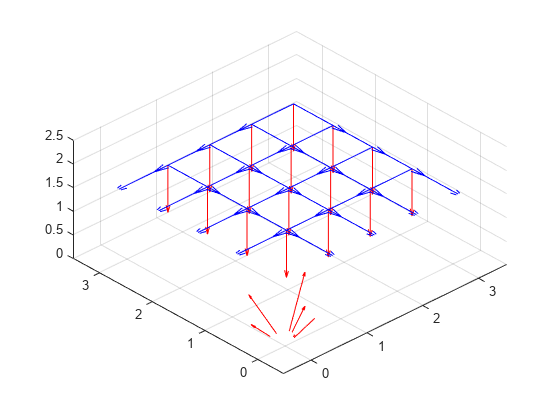

n_Positions = 400;
x_Positions = ceil(sqrt(n_Positions));
y_Positions = floor(sqrt(n_Positions));

x_distance = 3 / (x_Positions - 1);
y_distance = 3 / (y_Positions - 1);

rotations_per_position = 8;
rotator = 2*pi/(rotations_per_position);
rotator_deg = 360/(rotations_per_position);

mySensorArray = zeros(n_Positions * rotations_per_position, n_Emitters * n_Receivers);
myLocationArray = zeros (n_Positions * rotations_per_position, 3);

figure(20)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor);
axis([-0.5 3.5 -0.5 3.5 0 2.5]);
view(3);
grid on
view([-43.35 53.33]);
experiment = 0;

Current_X = 0.0;
Current_Y = 3.0;
Current_Theta = 0;

position_number = 0;

for l = 1: y_Positions
    if (~(l == 1))
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-y_distance,0));
        Current_Y = Current_Y - y_distance;
    end
    for m=1:x_Positions
        if (m == 1)

        elseif (mod(l,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(x_distance,0,0));
            Current_X = Current_X + x_distance;
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-x_distance,0,0));
            Current_X = Current_X - x_distance;
        end
        for n = 1: rotations_per_position
                Current_Theta = Current_Theta + rotator;
                if (Current_Theta == 2*pi)
                    Current_Theta = 0;
                end
                PDSensor=vlpMoveSensor(PDSensor, Trans3(-Current_X,-Current_Y,0));
                PDSensor=vlpMoveSensor(PDSensor, Trans3(0,0,0)*RotZ3(rotator));
                PDSensor=vlpMoveSensor(PDSensor, Trans3(Current_X,Current_Y,0));

            [ Y nu ] = vlpRecIndication( Emitters, PDSensor, Bw, Z, s_i, s_v, Z_p, Theta );
            position_number = position_number +1;

            for k = 1:n_Emitters
                new_Y = Y(:, k);
                new_Y = new_Y';
                for j = 1: n_Receivers
                    mySensorArray(position_number, k*n_Receivers - (n_Receivers - j)) = new_Y(j);
                    myLocationArray(position_number, 1) = Current_X;
                    myLocationArray(position_number, 2) = Current_Y;
                    myLocationArray(position_number, 3) = Current_Theta;
                end
            end

            Nu = repmat(nu,1,n_Emitters);
            
            s = sqrt(Nu).*randn(size(Y));
            Ystar = Y + s;
            
            Pr_v = sqrt(sum((Y.*Y),2));
            for k = 1:n_Receivers
               PDSensor(k).Pr = Pr_v(k);
            end
            pause(0.1)
            figure(20)
            delete(hx)
            % Plot the receiver power intensities, scaled
            hx = PlotHTMArrayPr(PDSensor);
        end
    end
end



% myArray


## Write the matrix in a .csv file

writematrix(mySensorArray, 'mySensorData.csv');
writematrix(myLocationArray, 'myLocationData.csv');
